# Lab 7: Fourier series analysis and synthesis

### Name : Purval Madhukar Bhude

### Roll No. S20230010193

### Section 4

## Question 1

#### part a)

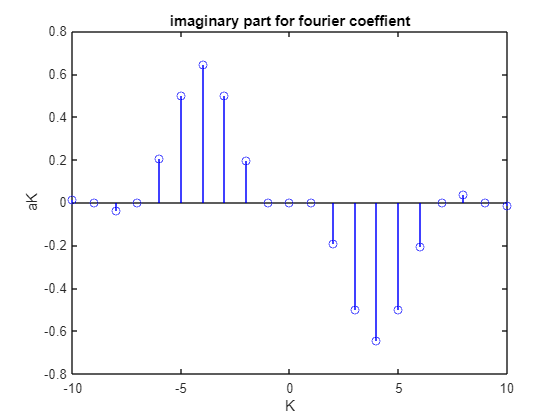

syms t;
x = 4*cos(t)*sin(4*t);
ak = ones(1,21);
for k=-10:10
    ak(k+11)=(1/(2*pi))*int(x*exp(-1j*k*t),t,-pi/2,pi/2);
end
k = -10:10; 
stem(k,imag(ak),"b");
title("imaginary part for fourier coeffient");
xlabel("K");
ylabel("aK");

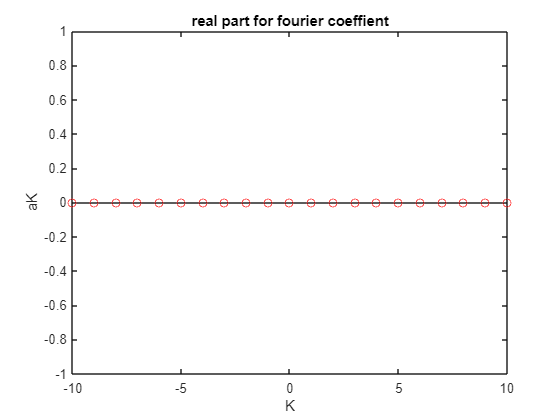

stem(k,real(ak),"r");
title("real part for fourier coeffient");
xlabel("K");
ylabel("aK");

#### part b)

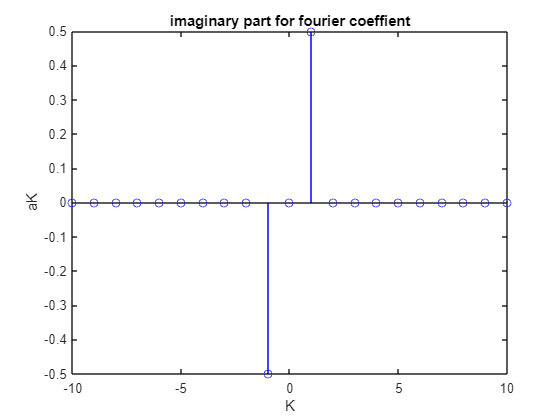

syms t;
x = cos(12*t) - sin(6*t);
ak = ones(1,21);
for k=-10:10
    ak(k+11)=(3/pi)*int(x*exp(-1j*6*k*t),t,-(pi/6),(pi/6));
end
k = -10:10; 
stem(k,imag(ak),"b");
title("imaginary part for fourier coeffient");
xlabel("K");
ylabel("aK");

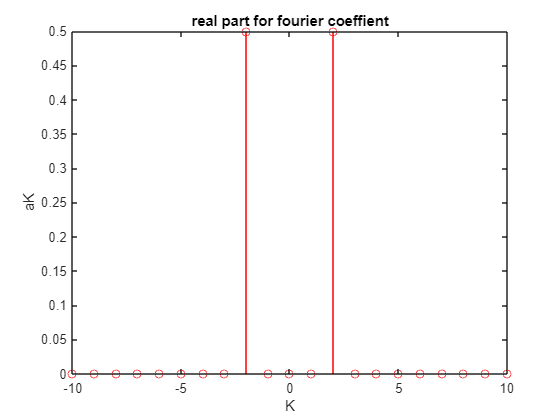

stem(k,real(ak),"r");
title("real part for fourier coeffient");
xlabel("K");
ylabel("aK");

#### part c)

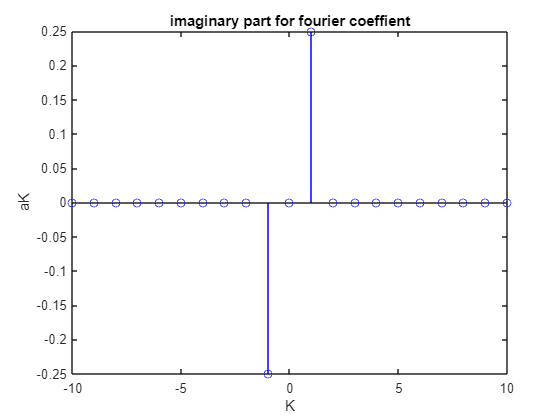

syms t;
x = (1/2)*(10 - sin(6*pi*t));
ak = ones(1,21);
for k=-10:10
    ak(k+11)=(3)*int(x*exp(-1j*6*pi*k*t),t,-(1/6),(1/6));
end
k = -10:10; 
stem(k,imag(ak),"b");
title("imaginary part for fourier coeffient");
xlabel("K");
ylabel("aK");

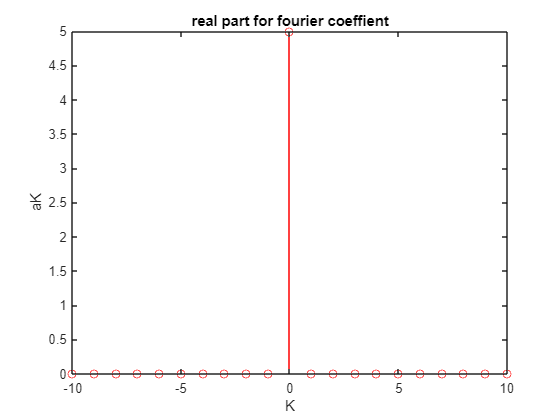

stem(k,real(ak),"r");
title("real part for fourier coeffient");
xlabel("K");
ylabel("aK");

#### part d)

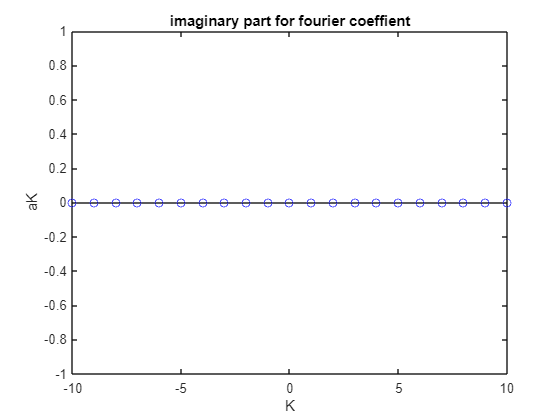

syms n;
x = 4.5;
ak = ones(1,21);
for k=-10:10
    ak(k+11) = (3)*int(x*exp(-1j*6*pi*k*t),t,-(1/6),(1/6));
end
k = -10:10;
stem(k,imag(ak),"b");
title("imaginary part for fourier coeffient");
xlabel("K");
ylabel("aK");

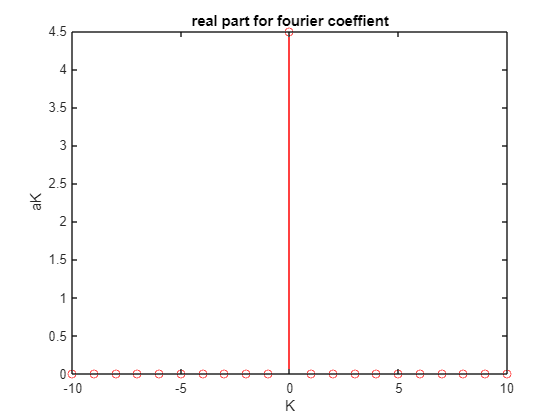

stem(k,real(ak),"r");
title("real part for fourier coeffient");
xlabel("K");
ylabel("aK");

#### part e)

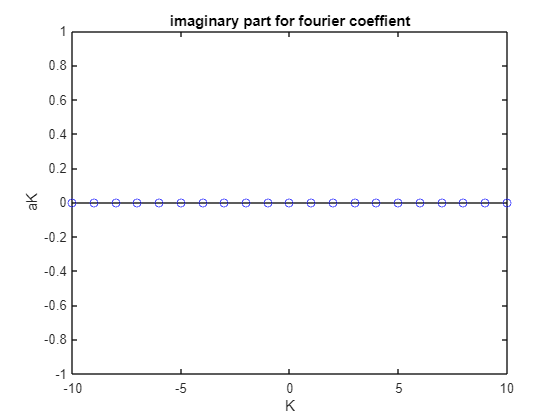

syms t;
x = 2;
ak = ones(1,21);
for k=-10:10
    ak(k+11)=int(x*exp(-1j*2*pi*k*t),t,-(1/2),(1/2));
end
k = -10:10; 
stem(k,imag(ak),"b");
title("imaginary part for fourier coeffient");
xlabel("K");
ylabel("aK");

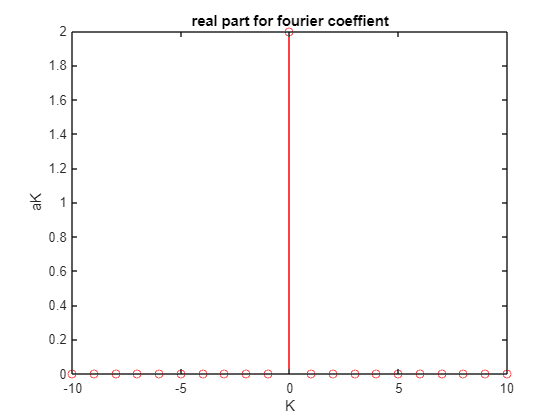

stem(k,real(ak),"r");
title("real part for fourier coeffient");
xlabel("K");
ylabel("aK");

## Question 2

#### part a)

syms t;
x = 4*cos(t)*sin(4*t);
ak = ones(1,21);
for k=-10:10
    ak(k+11)=(1/(2*pi))*int(x*exp(-1i*k*t),t,-pi/2,pi/2);
end
xN = 0;
for k = -10:10
    xN = xN + ak(k+10+1)*exp(1i*k*t);
end
e = x - xN;

#### part b)

syms t;
x = cos(12*t) - sin(6*t);
ak = ones(1,21);
for k=-10:10
    ak(k+11)=(3/pi)*int(x*exp(-1j*6*k*t),t,-(pi/6),(pi/6));
end
xN = 0;
for k = -10:10
    xN = xN + ak(k+10+1)*exp(1i*k*6*t);
end
e = x - xN;

#### part c)

syms t;
x = (1/2)*(10 - sin(6*pi*t));
ak = ones(1,21);
for k=-10:10
    ak(k+11)=(3)*int(x*exp(-1i*6*pi*k*t),t,-(1/6),(1/6));
end
xN = 0;
for k = -10:10
    xN = xN + ak(k+10+1)*exp(1i*k*6*pi*t);
end
e = x - xN;

## Question 3

#### part a)

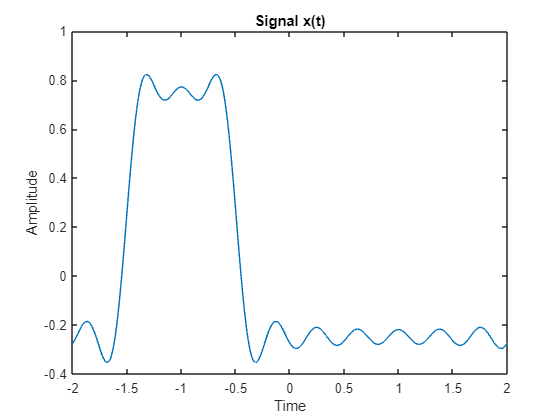

t = linspace(-2, 2, 1000);  

x = zeros(size(t));

for k = -10:10
    if k == 0
        ak = 0;
    else
        ak = ((1i)^k) * (sin(k*pi/4)) / (k*pi);
    end
    x = x + ak * exp(1i * 2*pi*k/4 * t);
end

plot(t, real(x));
xlabel('Time');
ylabel('Amplitude');
title('Signal x(t)');

#### part b)

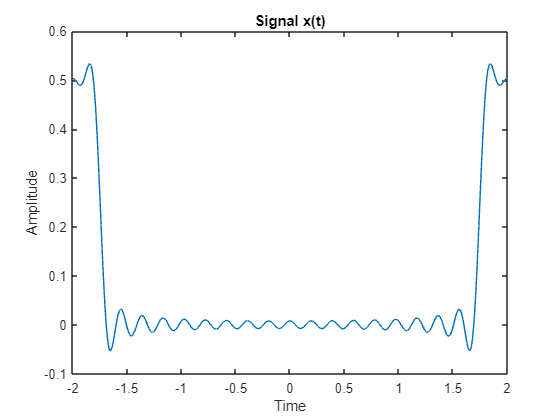

t = linspace(-2, 2, 1000);  

x = zeros(size(t));

for k = -10:10
    if k == 0
        ak = 1/16;
    else
        ak = ((-1)^k) * sin(k*pi/8) / (2*k*pi);
    end
    x = x + ak * exp(1i * 2*pi*k/4 * t);
end

plot(t, real(x));
xlabel('Time');
ylabel('Amplitude');
title('Signal x(t)');